clc
clear
close all

Lets create some random data

data_1 = rand(100,1);
data_2 = rand(100,1);
data_3 = randn(1000,1); % Normally distributed
data_4 = randn(1000,1); % Normally distributed
data_5 = randn(10000,1); % Normally distributed
data_6 = randn(10000,1); % Normally distributed

start with plotting data 1 and data 2

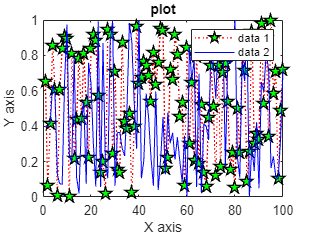

figure
plot(data_1,'r',LineStyle=":",LineWidth=1,Marker="pentagram",MarkerEdgeColor="k",MarkerFaceColor="g",MarkerSize=10)
hold on
plot(data_2,'b')
title('plot')
xlabel('X axis')
ylabel('Y axis')
legend('data 1','data 2')

Lets draw the scatter plot

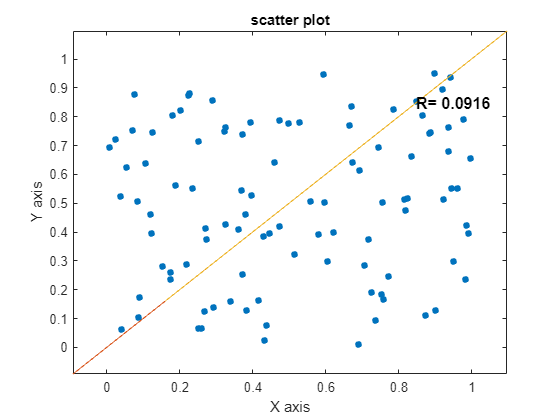

figure
gscatter(data_1,data_2)
x = [min(data_1,data_2)-0.1 max(data_1,data_2)+0.1];
pl = line(x,x);
correlation=corr(data_1,data_2);
text(max(max(data_1,data_2))-0.15, max(max(data_1,data_2))-0.15,...
    ['R= ',num2str(correlation,'%.4f')],'FontSize',12,'FontWeight','bold')
title('scatter plot')
xlabel('X axis')
ylabel('Y axis')
axis tight

Here we draw the histogram of data 3

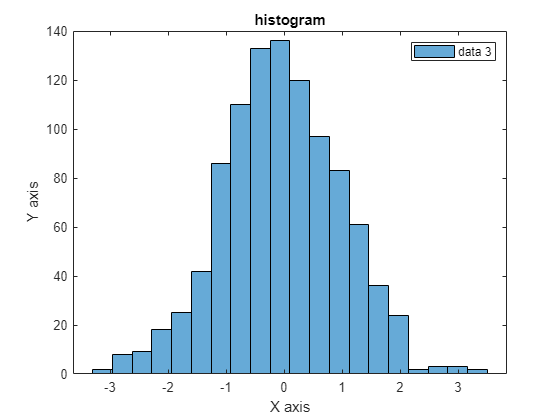

figure
histogram(data_3,20)
title('histogram')
xlabel('X axis')
ylabel('Y axis')
legend('data 3')

Now we go one step forward and draw the pdf plot of data 4

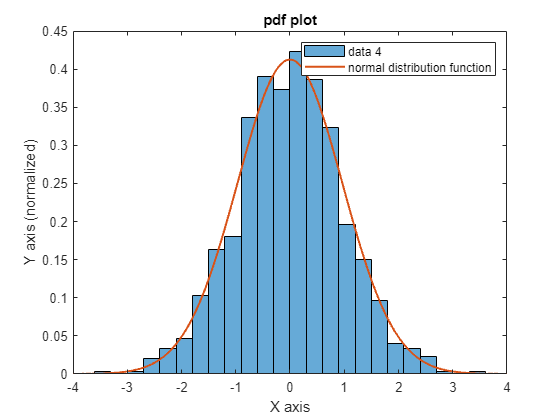

figure
histogram(data_4,'Normalization','pdf')
hold on
y = -4:0.01:4;
mu = mean(data_4);
sigma = std(data_4);
f = exp(-(y-mu).^2./(2*sigma^2))./(sigma*sqrt(2*pi));
plot(y,f,'LineWidth',1.5)
title('pdf plot')
xlabel('X axis')
ylabel('Y axis (normalized)')
legend('data 4','normal distribution function')

Here we draw the 2D histogram of data 5 and data 6

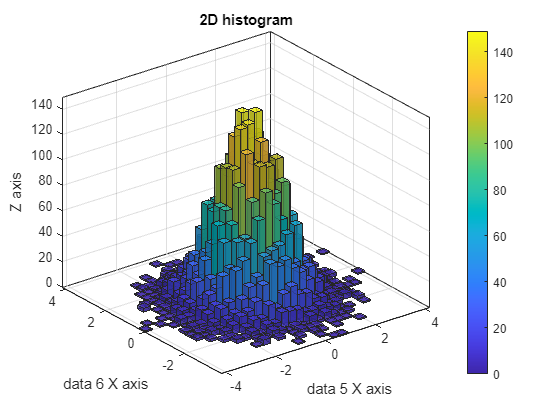

figure
histogram2(data_5,data_6,'FaceAlpha',0.7,'FaceColor','flat')
colorbar
title('2D histogram')
xlabel('data 5 X axis')
ylabel('data 6 X axis')
zlabel('Z axis')